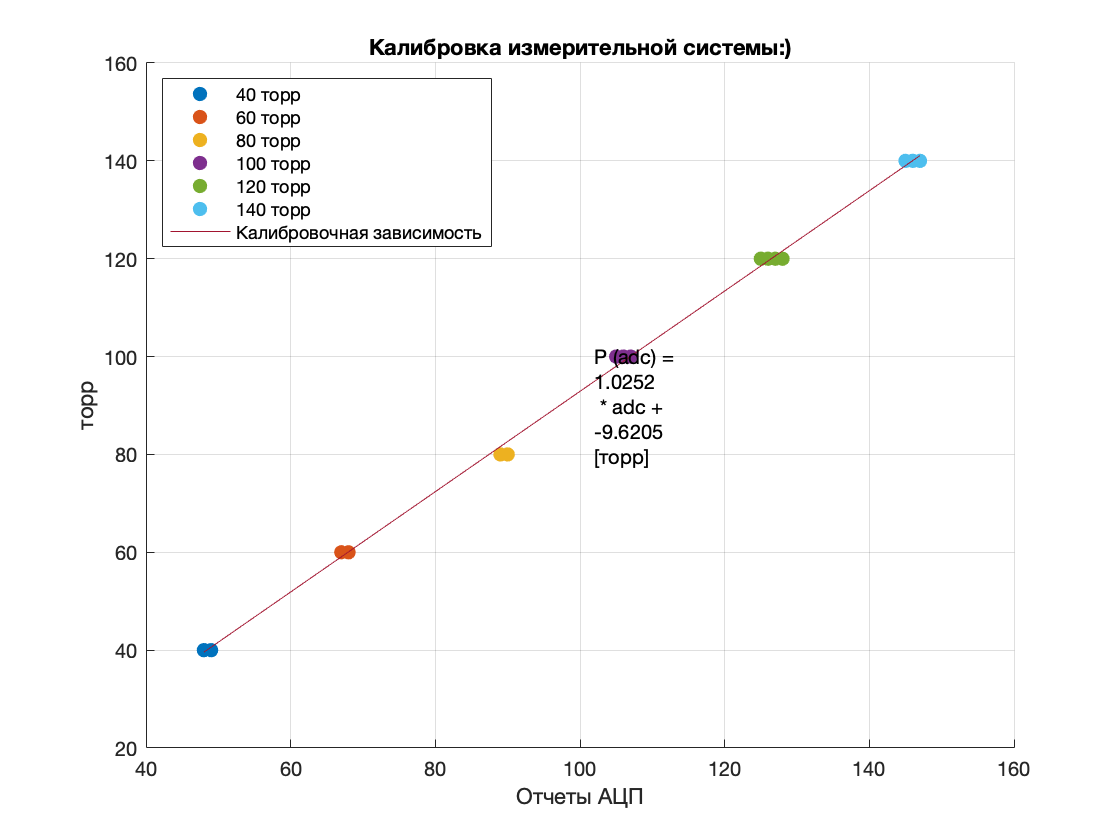

close all;
clear variables;


adc40 = fscanf(fopen("data/calibration_1.txt"), '%d');
adc60 = fscanf(fopen("data/calibration_2.txt"), '%d');
adc80 = fscanf(fopen("data/calibration_3.txt"), '%d');
adc100 = fscanf(fopen("data/calibration_4.txt"), '%d');
adc120 = fscanf(fopen("data/calibration_5.txt"), '%d');
adc140 = fscanf(fopen("data/calibration_6.txt"), '%d');

fclose("all");



torr40 = ones(length(adc40), 1) * 40;
torr60 = ones(length(adc60), 1) * 60;
torr80 = ones(length(adc80), 1) * 80;
torr100 = ones(length(adc100), 1) * 100;
torr120 = ones(length(adc120), 1) * 120;
torr140 = ones(length(adc140), 1) * 140;

cAdc = [adc40; adc60; adc80; adc100; adc120; adc140];
cTorr = [torr40; torr60; torr80; torr100; torr120; torr140];

c = polyfit(cAdc, cTorr, 1);

cFigure = figure("Name", "Калибровка", "NumberTitle","off");
hold all;

 plot(adc40, torr40, ".", "MarkerSize", 20);
 plot(adc60, torr60, ".", "MarkerSize", 20);
 plot(adc80, torr80, ".", "MarkerSize", 20);
 plot(adc100, torr100, ".", "MarkerSize", 20);
 plot(adc120, torr120, ".", "MarkerSize", 20);
 plot(adc140, torr140, ".", "MarkerSize", 20);
 
 plot(cAdc, polyval(c, cAdc));
 
 legend("40 торр", "60 торр", "80 торр", "100 торр", "120 торр", "140 торр","Калибровочная зависимость", "Location", "northwest");
 
 grid on;
 xlabel("Отчеты АЦП");
 ylabel("торр");
 title("Калибровка измерительной системы:)");
 text(mean(cAdc) * 1.05, mean(cTorr), ["P (adc) = ", num2str(c(1)), " * adc +", num2str(c(2)), "[торр]"]);
 
 saveas(cFigure, "Калибровка.png");

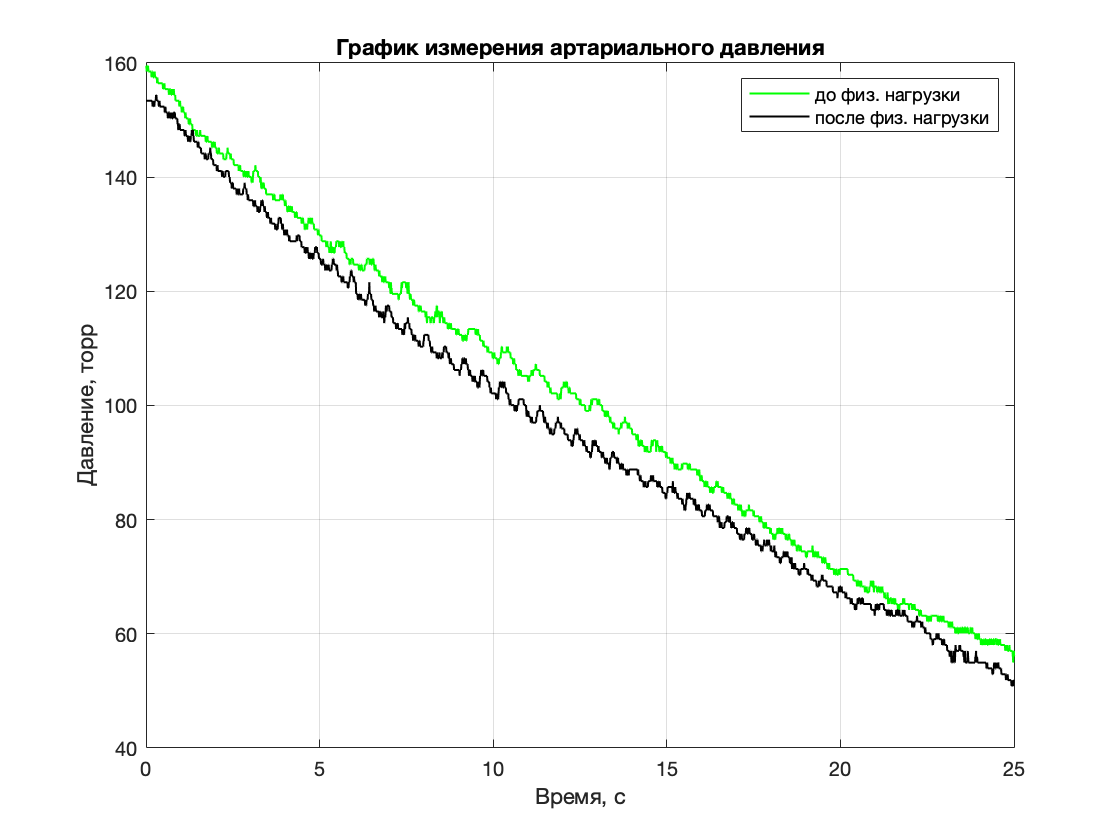

 
 dt = 0.01;
 
 adcBefore = fscanf(fopen("data/data_before.txt"), "%d");
 tBefore = linspace(0, length(adcBefore) * dt, length(adcBefore));
 pBefore = polyval(c, adcBefore);
 
 adcAfter = fscanf(fopen("data/data_after.txt"), "%d");
 tAfter = linspace(0, length(adcAfter) * dt, length(adcAfter));
 pAfter = polyval(c, adcAfter);
 
 
 pFigure = figure ("Name", "график давления", "NumberTitle","off");
 
 plot(tBefore, pBefore,"g", tAfter, pAfter, "k" , "LineWidth", 1 );
 legend("до физ. нагрузки", "после физ. нагрузки");
 
 grid on;
 xlim([0, 25]);
 
 xlabel("Время, с");
 ylabel("Давление, торр");
 title("График измерения артариального давления");
 
 saveas(pFigure, "давление.png");


 
cBefore = polyfit(tBefore, pBefore, 7) 

cBefore =     0.0000   -0.0000    0.0006   -0.0120    0.1118   -0.2505   -6.1340  158.5914


cAfter = polyfit(tAfter, pAfter, 5) 

cAfter =     0.0000   -0.0001   -0.0028    0.2070   -6.9104  155.1981



pulseBefore = pBefore - polyval(cBefore, tBefore)' 

pulseBefore =     0.9407
    1.0021
    0.0384
    1.1250
    1.1866
    0.2230
    1.3098
    0.3463
    0.4080
    0.4698


pulseAfter = pAfter - polyval(cAfter, tAfter)' 

pulseAfter =    -1.8169
   -1.7478
   -1.6788
   -1.6097
   -1.5408
   -1.4718
   -1.4029
   -1.3341
   -1.2653
   -1.1965



pulseFigure = figure('Name', 'Графики пульса', 'NumberTitle', 'off') 

pulseFigure =   Figure (3: Графики пульса) with properties:

      Number: 3
        Name: 'Графики пульса'
       Color: [0.9400 0.9400 0.9400]
    Position: [441 379 560 420]
       Units: 'pixels'

  Show all properties


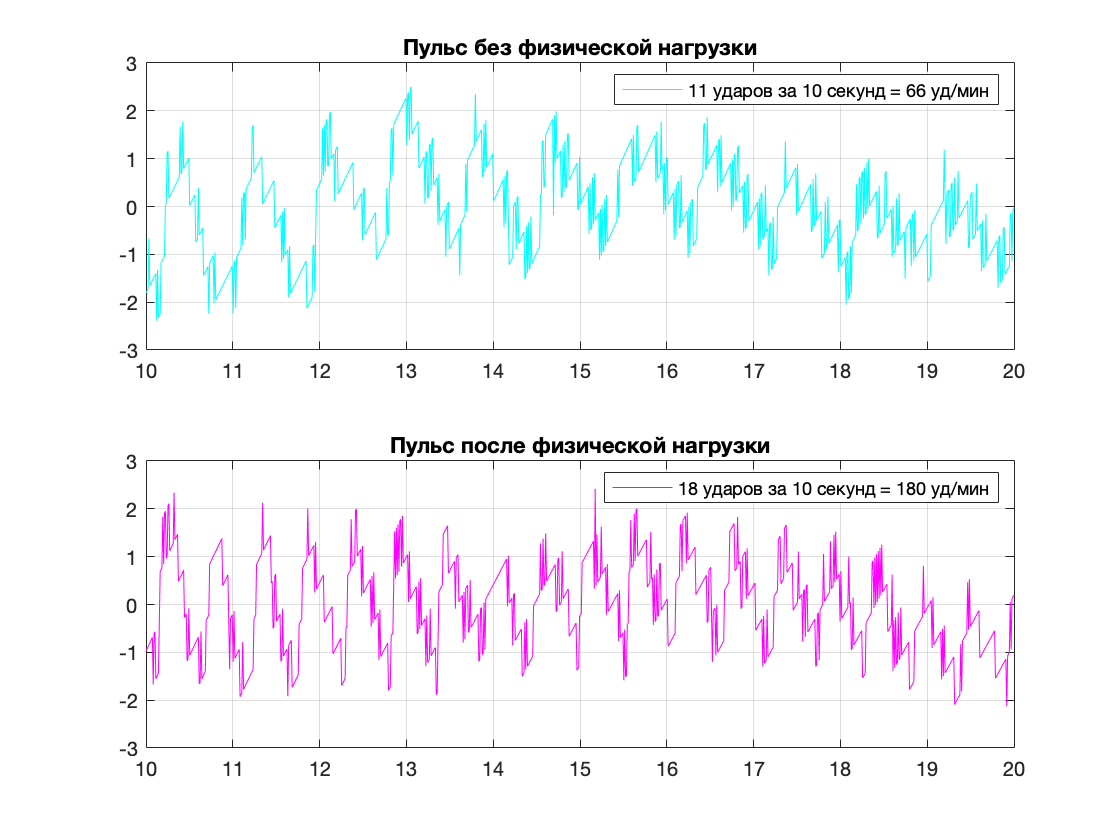


subplot(2, 1, 1) 
plot(tBefore, pulseBefore, "c") 
legend('11 ударов за 10 секунд = 66 уд/мин') 
grid on 
xlim([10,20]) 
title('Пульс без физической нагрузки') 

subplot(2,1,2) 
plot(tAfter, pulseAfter, "m") 
legend('18 ударов за 10 секунд = 180 уд/мин') 
title('Пульс после физической нагрузки') 
grid on 
xlim([10,20]) 

saveas(pulseFigure, 'Пульс.png')